**Clear Functions**

clear;
close all;
clc;

**Initial Conditions**

rE = 6378; % Radius of Earth (km)
mu = 3.986e5; %mu for Earth

% Inital position and velocity vectors

r0 = [-22680.21,-13923.69,92.92];
v0 = [0,0,sqrt(mu/norm(r0))];


**Convert from ECIF to ECEF**

utc = [2022 1 4 12 0 0];
[r_ecef,v_ecef] = eci2ecef(utc,r0,v0);

% Qxx = [cosd(omega), sind(omega), 0;
%     -sind(omega), cosd(omega), 0;
%     0, 0, 1];

% Convert the original matrices to vertial
% r0 = r0.';
% v0 = v0.';

% Calculate final state vector in ECEF
% rX = Qxx*r0;
% vX = Qxx*v0;

**Calculating Orbital Elements**

r = norm(r_ecef); % Calc distance
v = norm(v_ecef); % Calc speed
vR = (r_ecef(1)*v_ecef(1) + r_ecef(2)*v_ecef(2) + r_ecef(3)*v_ecef(3))/r; %Radial velocity
hV = cross(r_ecef,v_ecef); % Vector specific angular momentum
h = norm(hV); % Magnitude of specific angular momentum

i = acosd(hV(3)/h); % Inclination
% Node line
K = [0,0,1];
NV = cross(K,hV); % Node line vector
N = norm(NV); % Magnitude of node line


omegaRA = acosd(NV(1)/N); % Right Ascension (RA) of ascending node

if NV(2) < 0
    omegaRA = 360-omegaRA;
end


% Calculate eccentricity vector
eV = 1/mu*((v^2-mu/r)*r_ecef-r*vR*v_ecef);
e = norm(eV); % Magnitude of eccentricity vector

omega = acosd(dot(NV,eV)/(N*e)); % Argument of perigee

theta = acosd(dot(eV,r_ecef)/(e*r)); % True Anomaly

rp = (h^2/mu)*(1/(1+e*cosd(0))); % Perigee radii
ra = (h^2/mu)*(1/(1+e*cosd(180))); % apogee radii


a = 1/2*(rp+ra); % Semimajor axis (km)
T = (2*pi)*sqrt(a^3/mu);

**State Vector and Timespans**

s0 = [r_ecef;v_ecef];

timeSpan = 0:T;

**Call ODE45 Function**

*Note going to call multiple times for multiple orbits on same ECIF frame*

Inputs:* t, s, *$\mu$

Output: $\overrightarrow{\textrm{sol}}$

[~, sol] = ode45(@(t,s)diffEq(t,s,mu), timeSpan, s0); 

**Figure Configuration**

figure;

hold on; grid on; grid minor; axis equal; rotate3d on
xlabel('X (km)')
ylabel('Y (km)')
zlabel('Z (km)')
title('One GEO Orbits in ECEF')


[X, Y, Z] = sphere(); 

**Plotting Orbit and Earth**

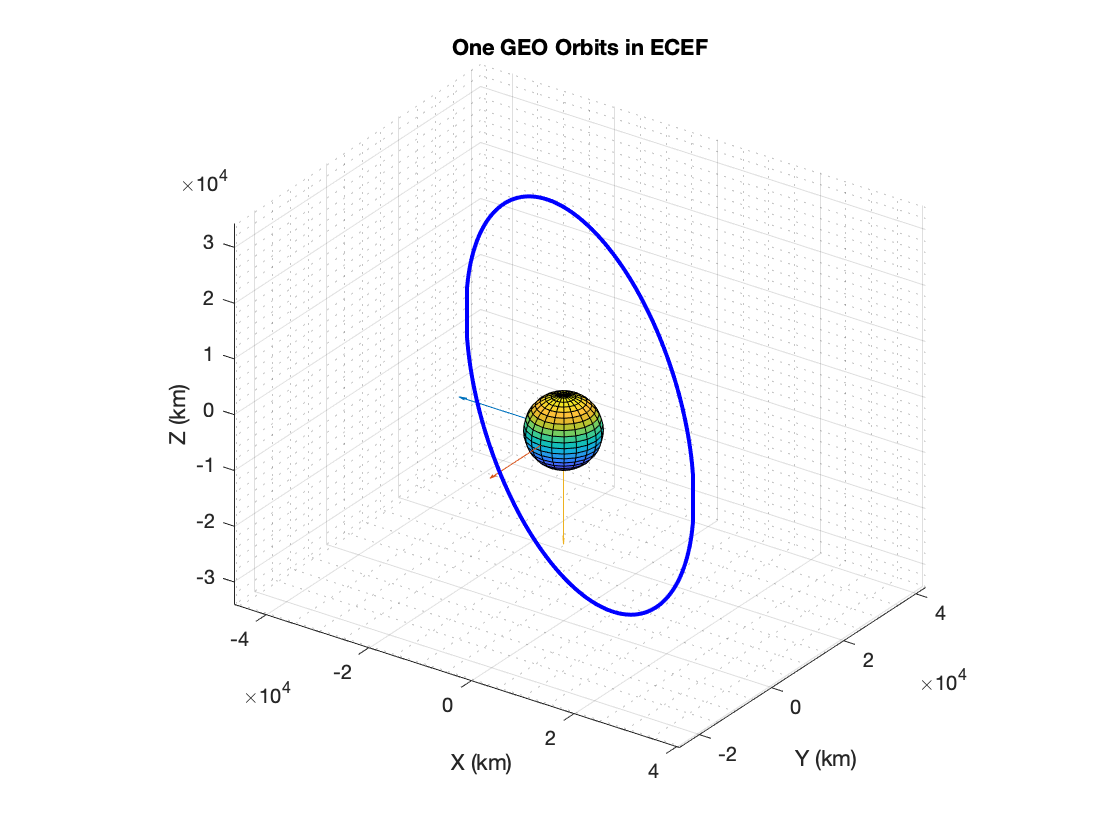

surf(X*rE, Y*rE, Z*rE)

% Draw Unit Vectors
quiver3(0,0,0,r0(1),0,0);
quiver3(0,0,0,0,r0(1),0);
quiver3(0,0,0,0,0,r0(1));

plot3(sol(:,1),sol(:,2),sol(:,3),'-b','LineWidth',2);

**Printing Outputs**

fprintf('\nGiven r = [\n%.0fI + %.0fJ +%.0fK]\n\n', r0(1), r0(2), r0(3));


Given r = [
-22680I + -13924J +93K]



fprintf('\nGiven v = [\n%.3fI + %.3fJ +%.3fK]\n\n', v0(1), v0(2), v0(3)); 


Given v = [
0.000I + 0.000J +3.870K]



fprintf('\nEccentrcity: %.2f', e);


Eccentrcity: 0.25

fprintf('\nPeriod = %.0f (sec)\n', T);


Period = 66864 (sec)


fprintf('\nEccentricity Vectors = [\n%.4fI + %.4fJ +%.4fK]', eV(1), eV(2), eV(3));


Eccentricity Vectors = [
0.0787I + -0.2400J +-0.0031K]

fprintf('\nSemi Major Axis = %.0f (km)\n', a);


Semi Major Axis = 35606 (km)


fprintf('Right Ascension = %.3f (degrees)\n',omegaRA);

Right Ascension = 287.797 (degrees)




fprintf('ECEF r = [\n%.3fI + %.3fJ +%.3fK]\n\n', r_ecef(1), r_ecef(2), r_ecef(3)');

ECEF r = [
8112.722I + -25346.626J +44.805K]



fprintf('ECEF v = [\n%.3fI + %.3fJ +%.3fK]\n\n', v_ecef(1), v_ecef(2), v_ecef(3)');

ECEF v = [
-1.850I + -0.600J +3.870K]



**ODE45 Function**

function sdot = diffEq(t,s,mu)

% r is first three elements, v is last three
rDQ = s(1:3);
vDQ = s(4:6);

sdot(1:3,1) = vDQ; %First three elements are velocity
sdot(4:6,1) = (-mu*rDQ)/(norm(rDQ))^3; % Actual two body EOM


end
